# MTH 600- Final Project

Name: Sophia Rybnik

Date: April 2024

#### Project Background

A typical practice in finance is to estimate an option pricing model from market prices of options that are traded frequently (in other words, liquid options). The calibrated model can be used to hedge liquid options or price and hedge other (illiquid) exotic options on the same underlying. In this project, we will consider the calibration of a local volatility function (LVF) model in practice.

The LVF model assumes the stock price as 

$\textrm{dS}=r\cdot \textrm{Sdt}+\sigma \left(S,t\right){\textrm{SdW}}_t$,

where $\sigma \left(S,t\right)=\max \left(0\ldotp 0,x_1 +x_2 S+x_3 S^2 \right)$. The European call option value is then the solution of the PDE

$V_{\tau \;} -\frac{\;\sigma^2 \left(S,\tau \;\right)}{2}{S^2 V}_{\textrm{SS}} -{\textrm{rSV}}_S +\textrm{rV}=0$, (1)

where $\tau =T-t$ is the time to maturity.

#### **I) Determining the Initial and Boundary Conditions**

We will first introduce some simple notation:

$V$ = the option value; a function of current value of the underlying asset and time, i.e. $V\left(S,t\right)$. 

The value of the option also depends on: 

$K$ = the exercise price; 

$T$ = the expiry time; 

$\sigma^2 \left(S,\tau \;\right)$ = the local volatility of the underlying asset; 

$r$ = the risk-free interest rate

For a European call option at maturity $T$, the payoff is determined by the choice to exercise or not exercise the contract. In terms of $T$, the terminal condition is given by $V\left(S,T\right)={\left(S-K\right)}^+$, where $S$ is the price of the underlying at $T$ . Considering the transformation $\tau =T-t$, the initial condition is then $V\left(S,0\right)={\left(S-K\right)}^+$. 

To solve the Black Scholes Local Volatilty Model numerically, the domain must be discretized, i.e. $\left\lbrack 0,S_{\max } \right\rbrack \times \left\lbrack 0,T\right\rbrack \ldotp$ Although the price of the underlying asset has an unbounded upside, i.e. $\left.\lbrack 0,\infty \right)$, an artificial limit $S_{\max \;}$is introduced for the purposes of discretization. If the price of the underlying is zero at maturity, the option contract will not be exercised. On the other hand, as the price tends to infinity (i.e. $S_{\max }$ in discretized space), the contract will be exercised and the payoff is discounted to today at the risk free rate. 

Thus, in discretized space, the boundary conditions are:


$$\left\lbrace \begin{array}{l}
V\left(0,t\right)=0\\
V\left(S_{\max } ,t\right)=\left(S_{\max } -K\right)\times \;e^{-\textrm{rt}} 
\end{array}\right.$$


#### **II) Computational Pricing**

#### **i. Monte Carlo Method**

Monte Carlo simulation can be used to price options by repeatedly taking random samples from an underlying distribution. Monte Carlo relies on risk-neutral valuation (see [https://en.wikipedia.org/wiki/Risk-neutral_measure](https://en.wikipedia.org/wiki/Risk-neutral_measure)). Under the risk-neutral measure $\mathbb{Q}$, the fair price of an option is the expectation of the payoff discounted at the risk-free rate.

The Monte Carlo technique can be applied to value an option, dependent on a single underlying $S$, as follows:

- Generate a large number of random price paths of the underlying, where $S$ is assumed to follow a Geometric Brownian motion. 

- For each path, calculate the exercise value/payoff of the option.

- Take the mean of the sample payoffs to get an estimate of the expected payoff in a risk-neutral world.

- Discount the expected payoff to today using the risk-free rate. 

The result is an estimate of the value of the option today. In pricing the option via the Monte Carlo method, anthithetic variates can be used as a variance reduction technique. In essence, the technique reduces the variance of the sample mean by introducing negative correlation between pairs of observations. This is done by taking the antithetic path of each sample and caculating the average expectation of the antithetic pair to reduce the variance of the sample mean (see [https://en.wikipedia.org/wiki/Antithetic_variates](https://en.wikipedia.org/wiki/Antithetic_variates) or [https://www.math.arizona.edu/~tgk/mc/book_chap5.pdf).](https://www.math.arizona.edu/~tgk/mc/book_chap5.pdf).) 

clear;
clc;

% define parameters
S0 = 1; % initial spot price
K = 1; % strice price
T = 0.25; % time to maturity
r = 0.03; % risk-free rate 
x1 = [0.2, 0.001, 0.003]; % parameters for local volatility model
M_mc = 10000; % number of monte carlo simulations
N = 100; % number of time steps

% monte carlo method
V0_mc = Eur_Call_LVF_MC(S0, K, T, r, x1, M_mc, N)

V0_mc = 0.0448

**ii. Finite Difference: Explicit Method**

To numerically solve a continuous differential equation, such as the Black-Scholes PDE, finite differences can be used to approximate the continuous time (and price) derivatives. Many published papers further explain how we can arrive at the discretized Black-Schole's PDE (see [https://www.researchgate.net/publication/243112801_Numerical_Approximation_of_Black-Scholes_Equation).](https://www.researchgate.net/publication/243112801_Numerical_Approximation_of_Black-Scholes_Equation).) 

As shown in part I, for numerical purposes the option price is modelled by a lattice in discrete dimensions: time runs from 0 to maturity and price runs from 0 to a high value, given by $S_{\max }$.  Recall that the initial and boundary conditions are given by:


$$\left\lbrace \begin{array}{l}
V\left(S,0\right)={\left(S-K\right)}^+ \\
V\left(0,t\right)=0\\
V\left(S_{\max } ,t\right)=\left(S_{\max } -K\right)\times \;e^{-\textrm{rt}} 
\end{array}\right.$$


The option price can be solved for in different ways by modifying the approximation of the time derivative. We can solve the price explicitly if using the forward difference approximation, implicitly using the backward difference or semi implicitly by equal weighting the implicit and explicit methods (i.e. the Crank–Nicolson method). These techniques work such that the value at each lattice point is a function of the value at later and adjacent lattice points. After the PDE is discretized per the technique chosen, the values at the remaining lattice points are calculated by iterating backwards in time from maturity ($\to \tau =0$) and inwards from the boundary prices ($\to S=0$).

More practically speaking, an option can be priced today using the explicit finite difference method as follows:

- Use a forward difference approximation for the time derivative $V_{\tau \;}$ and a symmetric central difference approximation for the second order price derivative$V_{\textrm{SS}}$. The first order price derivative $V_S$ is approximated by either central or forward difference approximation to ensure positive coefficient discretization (to promote stability).

- After plugging the finite difference approximations into (1), the resulting equation can be represented as a matrix of coefficients $A$.

- The matrix of option prices $V$ is initialized accounting for the implied initial and boundary conditions. Then, working backwards in time from $\tau =T$ to $\tau =0$, we can solve the system $AV_i^{n+1} =V_i^n$. Given that $A$ is a tri-diagonal matrix, the LU decomposition algorithm provides a fast and efficient method to solve for $V_i^{n+1}$. 

- Then, the value of the option today given the spot price of the underlying can be interpolated from the lattice. 

M_fd = 30; % number of stock price steps
Smax=3; % upper bound of the stock price

% finite difference method
V0_fd = Eur_Call_LVF_FD(S0, K, T, r, x1, Smax, M_fd, N)

V0_fd = 0.0489

**III) Model Calibration**

**i. Purpose**

In the Black-Scholes model (1), the unknown variable is $\sigma {\;}^2 \left(S,\tau \;\right)$. The remaining parameters are deterministic and easily observed. In part II, the option prices are computed using some given values of $x=\left\lbrack x_1 ,x_2 ,x_3 \right\rbrack$ as input for the local volatility function. We want our model to obtain the best fit between the generated prices and some observed market prices. In order to do so, we need to fit the volatility function to market data to determine the optimal parameters for $x$. By optimizing the parameters of the volatility function, we can get our model to generate prices which are more closely consistent to the prices of liquidly traded options.

**ii. Method**

Assume that the initial market prices $V_0^{\textrm{mkt}} \left(K_j ,T_j \right),j=1,2,\ldotp \ldotp \ldotp ,m$, are available; here $\left(K_j ,T_j \right)$ denotes the strike and expiry of the $j^{\textrm{th}}$ option.

Assume that $V_0 \left(K_j ,T_j ;x\right)$ denotes the initial value of an option with strike $K_j$ and $T_j$ under a LVF model described by a set of parameters $x=\left\lbrack x_1 ,x_2 ,\ldotp \ldotp \ldotp ,x_n \right\rbrack$. In the quadratic local volatility model (1), the model parameters are $\left\lbrack x_1 ,x_2 ,x_3 \right\rbrack$.

The model which best fits the market option prices can be estimated by solving the following non linear least squares problem

$\min_{x\in \Re^n } \frac{1}{2}\sum_{j=1}^m {\left(V_0 \left(K_j ,T_j ;x\right)-V_0^{\textrm{mkt}} \left(K_j ,T_j \right)\right)}^2$, (2)

Let $F\left(x\right)$ denote the vector of model option value errors from the market prices:


$$F\left(x\right)=\left\lbrack \begin{array}{c}
V_0 \left(K_1 ,T_1 ;x\right)-V_0^{\textrm{mkt}} \left(K_1 ,T_1 \right)\\
\vdots \\
V_m \left(K_m ,T_m ;x\right)-V_0^{\textrm{mkt}} \left(K_m ,T_m \right)
\end{array}\right\rbrack$$


Vector $F\left(x\right):\;\Re^n \to \Re^m$ is a nonlinear function of the model parameter $x\in \Re^n$ and the calibration problem (2) is equivalently formulated as 

$\min_{x\in \Re^n } \left(f\left(x\right)\overset{\textrm{def}}{=} \frac{1}{2}{\left\|F\left(x\right)\right\|}_2^2 \right)$, (3)

A nonlinear least squares problem (3) can be solved by a special optimization method such as the Levenberg-Marquardt method, the Gauss Newton method, or a general method for nonlinear unconstrained optimization problems.

Optimization methods for nonlinear least squares problems typically exploit the special structure of the gradient and Hessian of the function ${\left\|F\left(x\right)\right\|}_2^2$. They typically require computation of the Jacobian matrix of $F\left(x\right)$


$$J\left(x\right)=\left\lbrack \begin{array}{cccc}
\frac{\partial \;F_1 }{\partial \;x_1 } & \frac{\partial \;F_1 }{\partial \;x_2 } & \cdots  & \frac{\partial \;F_1 }{\partial \;x_n }\\
\frac{\partial \;F_2 }{\partial \;x_1 } & \frac{\partial \;F_2 }{\partial \;x_2 } & \cdots  & \frac{\partial \;F_2 }{\partial \;x_n }\\
\vdots  & \vdots  & \ddots  & \vdots \\
\frac{\partial \;F_m }{\partial \;x_1 } & \frac{\partial \;F_m }{\partial \;x_2 } & \cdots  & \frac{\partial \;F_m }{\partial \;x_n }
\end{array}\right\rbrack$$


One difficulty in solving the nonlinear least squares calibration problem (2) is that it is not easy to compute the Jacobian matrix $J\left(x\right)$ explicitly. Instead, a finite difference approximation of the Jacobian matrix can be computed.

**iii. Results**

The calibration problem will be solved using the Matlab function lsqnonlin with LevenbergMarquardt as the choice of the optimization method. The Monte Carlo method implemented above is used to evaluate $V_0 \left(K,T,x\right)$. 

The market prices used for model calibration are:

The options have expiry in three months and the risk-free rate remains at 3%. 

x0_1 = [0.2; 0.0; 0.0]; % initial parameter guess
[x1, resnorm1] = calibrate_parameters(x0_1) % Invoke optimizer


                                        First-order                     Norm of 
 Iteration  Func-count      Resnorm      optimality       Lambda           step
     0           1        0.0789459           0.219         0.01
     1           2         0.047977           0.242        0.001       0.189367
     2           3        0.0201113          0.0679       0.0001       0.311795
     3           4        0.0198952          0.0765        1e-05       0.125279
     4           7        0.0194675          0.0467        0.001       0.152321
     5           8        0.0180742          0.0439       0.0001       0.258538
     6           9        0.0160498          0.0845        1e-05      0.0662093
     7          21                                                 8.83893e-08

Local minimum possible.
lsqnonlin stopped because the relative 

x1 =     0.4809
    0.4045
         0


resnorm1 = 0.0160

x0_2 = [0.2; 0.1; 0.01]; % initial parameter guess
[x2, resnorm2] = calibrate_parameters(x0_2) % Invoke optimizer


                                        First-order                     Norm of 
 Iteration  Func-count      Resnorm      optimality       Lambda           step
     0           1        0.0612672           0.243         0.01
     1           2        0.0281614           0.113        0.001       0.238045
     2           3        0.0206602          0.0374       0.0001       0.115916
     3           4        0.0157075          0.0757        1e-05       0.137804
     4          16                                                 8.21271e-08

Local minimum possible.
lsqnonlin stopped because the relative size of the current step is less than
the value of the step size tolerance.

<

x2 =     0.5607
    0.0304
    0.1060


resnorm2 = 0.0157

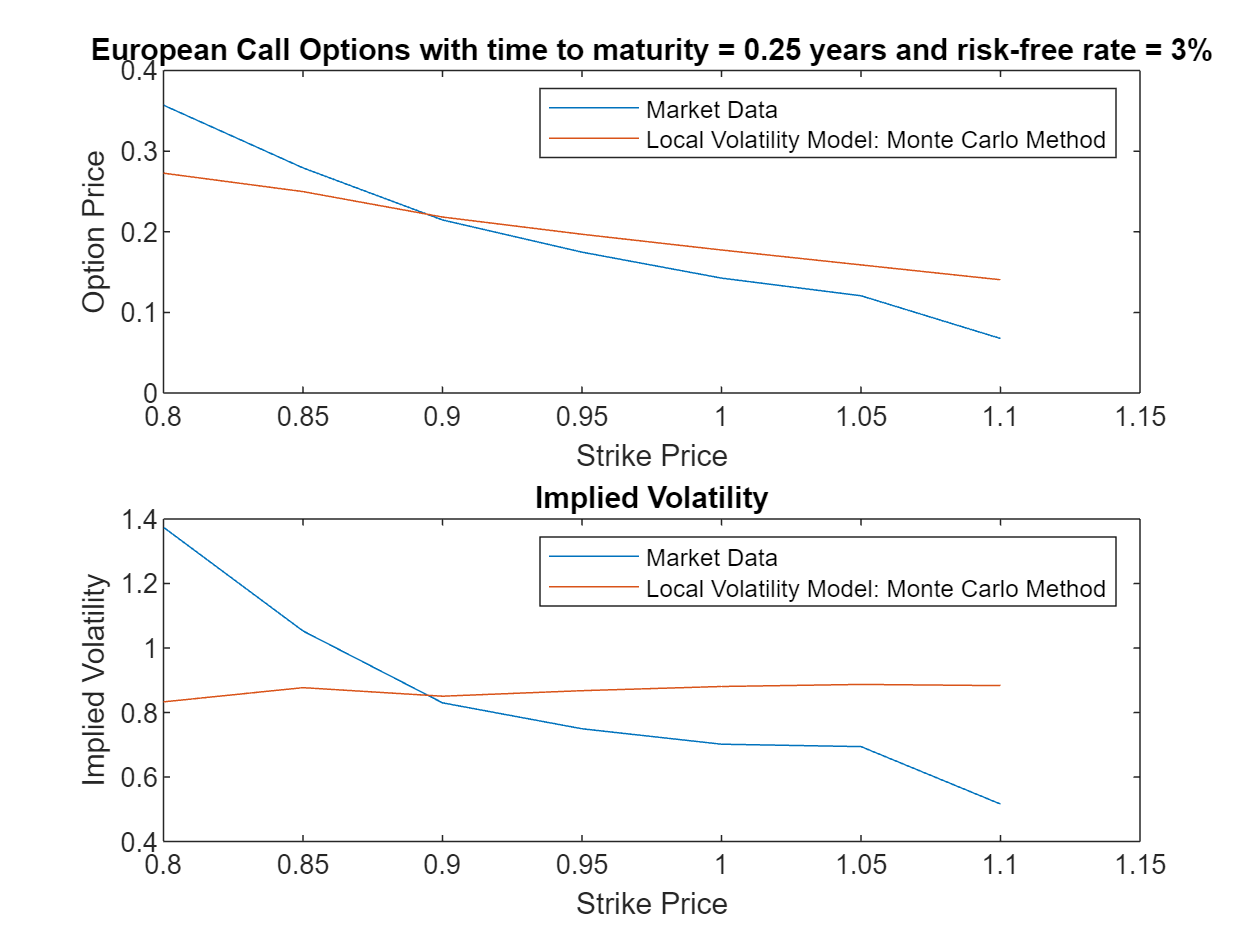

impliedvolplots(x1) % graph

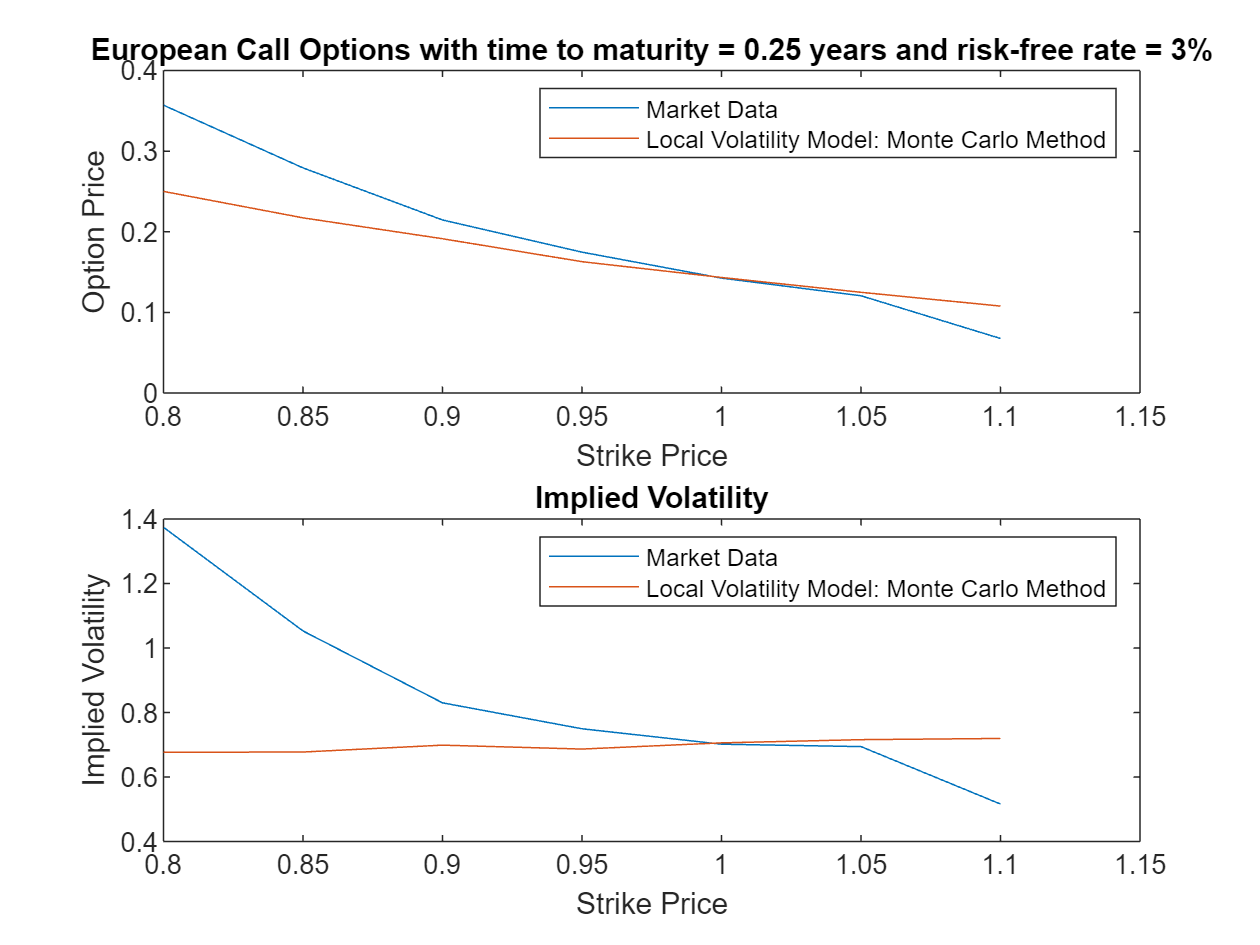

impliedvolplots(x2) % graph

From only looking at the value of the sum of the squared residuals from the calibration output, we cannot determine the extent to which the matlab program is successful in solving the optimization problem. We would have to further investigate the mean and distribution of the residuals, if they are uncorrelated with the independent and dependent variables, etc. However, from looking at the plots of the option prices and implied volatilities generated by our model, we can see that they significantly deviate from observed market values. The source of error may come from both the model itself and the calibration of its parameters. 